# **PRACTICE 6 - OPTIMIZATION TECHNIQUES**

**Andrés Herencia and Antonio Fernández**

**MUTECI 2023-2024**

**Exercise**

Let the classification problem be identified by `square4.txt` (in text format) or `square4.xlsx` (Excel format). In this problem, a set of data is identified by the cartesian coordinates (first two values) and a category (third value) that takes the values {0, 1, 2, 3}.

The objective of the practice is to become familiar with the heuristic optimization procedures, so a grouping or clustering problem will arise if the category variable is not used; therefore, in subsequent implementations you should NOT use the third variable, which is only provided for later checks.

Then, the following is requested:

## 1. Problem comprehension and modelization.

### a) Plot the data (filtering by category)

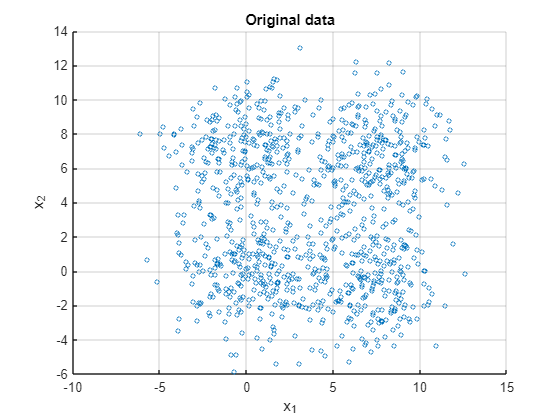

clc, clear, clf
cd 'C:\Users\andre\Documents\UNIVERSIDAD\MUTECI\BLOQUE 2\TOPT\lab\P6'
data = importdata('square4.txt', ',',1);
X1 = data.data(:, 1); X2 = data.data(:, 2); Y = data.data(:,3); % category;

figure(1)
scatter(X1, X2, 'SizeData', 10)
grid on
xlabel("x_1")
ylabel("x_2")
title('Original data')

Filtering by category...

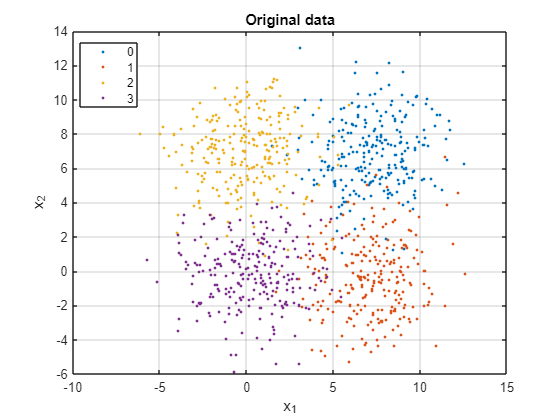

figure(2)
gscatter(X1, X2, Y)
grid on
xlabel("x_1")
ylabel("x_2")
title('Original data')

### b) If the number of categories is unkwown, try to figure out which is the most appropiate number of clusters for this problem: think about 2, 3 and 4 categories.

#### Two clusters

With two clusters, the data can be discriminated in horizontal and vertical ways. Since data seems to spread normally distributed over the plane, we can assume that a linear discriminator that passes through the mean of each point could be adapted to the problem. 

mean(X1)

ans = 3.6822

mean(X2)

ans = 3.3593

Then, two possible groups could be: 

- One group above the line $x_2=3.6822$, and another below that line.

- One group on the right of $x_1=3.3593$, and one is on the left.

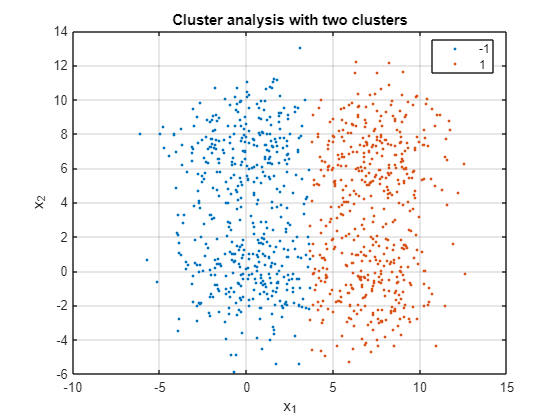

C = zeros(1,length(X1));
idxa = X1>=mean(X1);
idxb = X1<mean(X1);

C(idxa) = 1;
C(idxb) = -1;

figure(3)
gscatter(X1, X2, C)
grid on
xlabel("x_1")
ylabel("x_2")
title('Cluster analysis with two clusters')

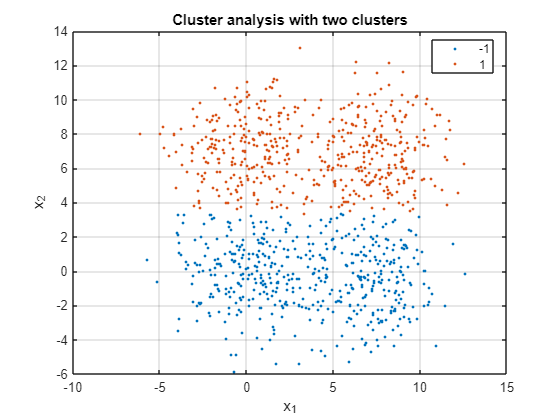

idxc = X2>=mean(X2);
idxd = X2<mean(X2);
C(idxc) = 1;
C(idxd) = -1;

figure(4)
gscatter(X1, X2, C)
grid on
xlabel("x_1")
ylabel("x_2")
title('Cluster analysis with two clusters')

Both models fit well, but they can be combined in 4 groups instead of 2-by-2. So, two clusters are not a suitable number of groups for this problem.

#### Three clusters

It does not makes sense to distribute the data across 3 groups because the shape of all data joined it seems like a "window" with 4 squares, or a big square, and the number of points is equally distributed only in pair groups. 

#### Four clusters

As we aforementioned, four groups seems to be a good approximation for our data distribution.

### c) Propose a distance or difference measure for the data.

Since we are working in a cartesian plane, we could make use of the eculidean distance, i.e., $d_{i,j} = \sqrt{x_j^2 - x_i^2}$. This distance suits with every kind of data that works with a canonical vectorial kernel. But, since our data is distributed in a shape of a square, a better solution could pass by considering the Mikowski distance of infinite order, this is, **the Chebysev distance**.

The Minkowski distance of order $p$ (where $p$ is an integer) between two points

$X= (x_1,x_2,\dots,x_n), Y= (y_1,y_2,\dots,y_n)$, where $X,Y\in	\mathbb{R}^n$

is defined as:


$$\left(\sum_{i=1}^{n} |x_i - y_i|^p\right)^{\frac{1}{p}}$$


We obtain the classical Euclidean distance when $p=2$, and we obtain the manhattan distance when $p=1$. But, when $p \to \infty$, the distance over a circle unit plots a square.

The following figure shows unit circles (the [level set](https://en.wikipedia.org/wiki/Level_set) of the distance function where all points are at the unit distance from the center) with various values of $p$:

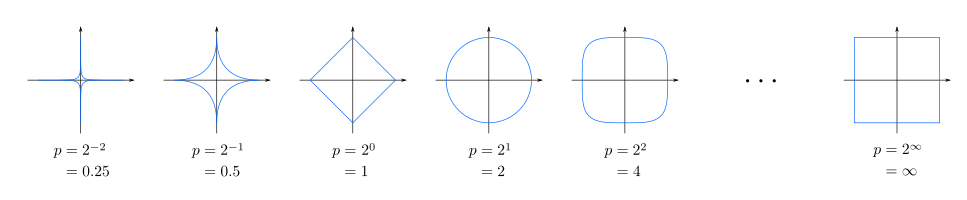

So, our choosen distance is the Cherbysev distance:


$$\lim_{p\to \infty}{\left(\sum_{i=1}^{2} |x_i - y_i|^p\right)^{\frac{1}{p}}}$$


### d) Identify the problem as an optimization problem indicating the decision variable, objective function and restrictions.

A data set consists of $d_i = \{(x_1,y_1), (x_2,y_2), \dots, (x_n,y_n)\},$ data points which will be distributed among $c_j = \{c_1, c_2, \dots, c_k\}, c_j=(x_{j}^{'},y_{j}^{'})$ clusters. The data points are assigned to the correct clusters by minimizing the sum of the Cherbysev distance between each data point and cluster centroid. This distance is denoted $r_i$ for $i=1,2,\dots,n$.

Then, the problem can be formulated as follows:

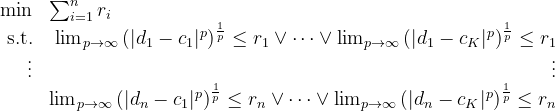

Where de decission variable is $k$, the number of clusters.

Since the data point can only belong to one cluster, we introduce the logicals or statement that we can see in the expression.

## 2. Propose a voracious constructive procedure to obtain an initial solution quickly.

- **Initialize centers:** we select the $K$ initial clusters centers $c_1, c_2, \dots, c_K$ taking randomly $k$ different data points.

- **Assign Points to Clusters:** For each point $d_i$, calculate the distances to all cluster centers using the expression: $\lim_{p\to \infty}{\left(|d_1 - c_1|^p\right)^{\frac{1}{p}}, \dots, \lim_{p\to \infty}{\left(|d_1 - c_K|^p\right)^{\frac{1}{p}} }}$. Assign $d_i$ to the cluster whose distance is the smallest among all clusters.

- **Update centers: **recalculate the cluster centers by taking the mean of all points assigned to each cluster: $c_K=\frac{1}{\text{points in cluster k}}\sum_{i} d_i$.

- **Repeat steps 2 and 3: **repeat the assignment and update steps until convergence or a predetermined number of iterations.

- **Calculate Objective Function:** Calculate the objective function value based on the obtained solution.

## 3. Based on the proposed model, given a generic solution, define a set of neighbors of said solution.

Little modifications of the previous problem can be made in order to obtain the neighbours of the solution. The following are proposed:

**1. Perturbation of Cluster Centers:**

- Randomly select one or more cluster centers.

- Perturb (add or subtract a certain amount to each cluster center initialization).

**2. Combination of Center and Radius Perturbations:**

- Combine the above two perturbations, i.e., perturb both cluster centers and radii simultaneously.

**3. Swap Points between Clusters:**

- Randomly select two clusters.

- Swap a random point between the selected clusters.

**4. Add or Remove Cluster:**

- Randomly add a new cluster with a random center and radius.

- Randomly remove one of the existing clusters.

**5. Local Search Neighborhood:**

- Perform a local search around the current solution by iteratively moving towards improving solutions within a local radius.